Aproximación con diferencias finitas usando la condición inicial  $ $$ u_0(x) = \max\{x-k,0\} $$$.

M = 250;
P = 2*M^2;
k = 0;
u0 = @(x) max([x-k 0]);
F = @(x) max([x,0]);
T = 4;
a=-1;
b=1;
u = FiniteDifApprox(u0,F,M,P,T,a,b);

display(u);

u =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

Gráfica

dx = (b-a)/(M);
dt = T/(P);
x = [-1:dx:1];
u0_vec = zeros(M+1);
for j=1:M+1
    u0_vec(j) = u0(dx*j-1);
end
%plot(x,u(P,:));
%plot(x,u0_vec);
%display(u(5,M));
%display(u0_vec(M+1));
supy = 2;
% for t=1:P
%     plot(x,u(t,:));
% 
%     %xlim([-1,1]);
%     %ylim([0,supy]);
%    % supy = sqrt(supy)*supy;
%     pause(0.5);
% end

Podemos explorar otras condiciones iniciales como$
 u_0(x) = \max\{x-\frac{1}{4},0\}$ si $x \in [0,\frac{1}{2})$ y $ u_0(x) = \max\{-x+\frac{3}{4},0\}$  si $x \in [\frac{1}{2},1]$.

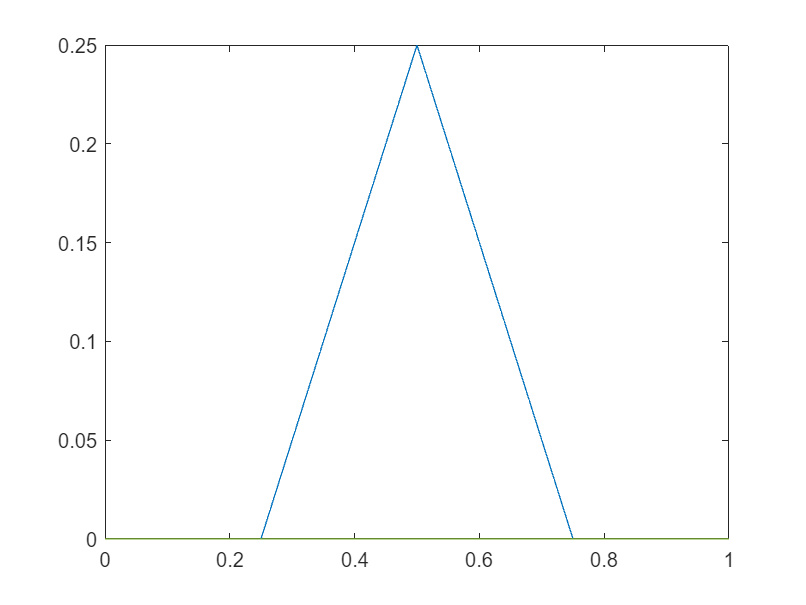

a = 0;
b = 1;
T = 1;
M = 200;
dx = 1/M;
x = [a:dx:b];
P = M^2;
dt = 1/P;
t = [a:dt:b];

plot(x,CasaAcampar(x));

Ahora aproximamos la solución con estas condiciones iniciales

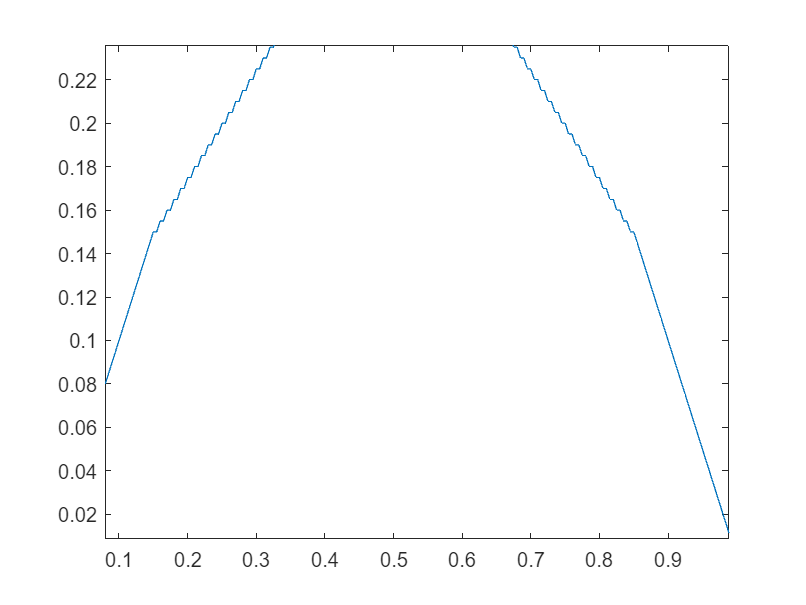

dx = (b-a)/(M);
dt = T/(P);
x = [a:dx:b];
u0_vec = zeros(M+1);
u0 = @(x) CasaAcampar(x);
u = FiniteDifApprox(u0,F,M,P,T,a,b);
% for j=1:M+1
%     u0_vec(j) = CasaAcampar(dx*j-a);
% end

%display(CasaAcampar(0.5));
% plot(x,u0_vec);

for t=1:P
    plot(x,u(t,:));

    %xlim([-1,1]);
    %ylim([0,supy]);
   % supy = sqrt(supy)*supy;
    pause(0.5);
end

% 
% u = zeros(P+1,M+1);
%     for j=1:M+1
%         u(1,j) = CasaAcampar((j-1)*dx+a);
%     end
%     for n=1:P
%         for j=2:M
%             ulap = (u(n,j+1)+u(n,j-1)-2*u(n,j))/(dx^2);
%             u(n+1,j) = u(n,j) + dt*(F(ulap));
%         end
%         u(n,M+1) = u0(b);
%         u(n,1) = u0(a);
%     end

Funciones

function [u] = FiniteDifApprox(u0,F,M,P,T,a,b)
    dt = T/(P);
    dx = (b-a)/(M);
    u = zeros(P+1,M+1);
    for j=1:M+1
        u(1,j) = u0((j-1)*dx+a);
    end
    for n=1:P
        for j=2:M
            ulap = (u(n,j+1)+u(n,j-1)-2*u(n,j))/(dx^2);
            u(n+1,j) = u(n,j) + dt*(F(ulap));
        end
        u(n,M+1) = u0(b);
        u(n,1) = u0(a);
    end
 
end


function [val] = CasaAcampar(x)
    N = length(x);
    val = zeros(N);
    for i =1:N
        if (0.25<=x(i)) && (x(i)<0.5)
            val(i) = max(x(i)-0.25,0);
        elseif (0.5<=x(i)) && (x(i)<0.75)
            val(i) = max(-x(i)+0.75,0);
        end
    end

end

function [val] = CasaAcamparEscalar(x)
        val = 0;
        if (0.25<=x) && (x<0.5)
            val = max(x-0.25,0);
        elseif (0.5<=x) && (x<0.75)
            val = max(-x+0.75,0);
        end

end